# Systwem of Autonomous Diff Eqns 

% dx1/dt = -x1+5; dx2/dt = 3*x2
% Linear SYstem with A = [-1 0; 0 3]; eq pt = (5,0)
% Unstable bcoz real(eig) > 0 

% Initial Values 
Np=11; 
[x,y]=meshgrid(linspace(3,7,Np), linspace(-1,1,Np));
dx = -x+5;
dy = 3*y;
x0=5; y0=0; 

% Phase Portrait Drawing 
figure(1); clf; hold on; 
quiver(x,y,dx,dy,'k');
plot(x0, y0, 'ro', 'MarkerFaceColor','r'); axis tight; 

% Linear System Solution
ex3 = @(t,x) [-x(1)+5; 3*x(2)] % RHS

ex3 = function_handle with value:
    @(t,x)[-x(1)+5;3*x(2)]


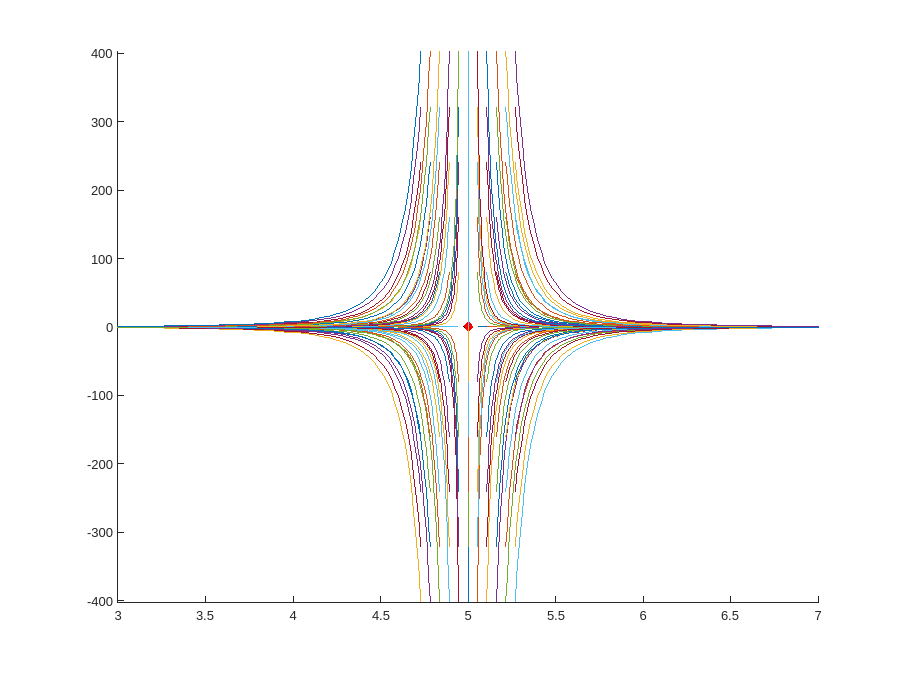

tspan = [0, 2];
for Nx=1:size(x,1)
    for Ny=1:size(x,2)
        % Initial Conditions
        x0=x(Nx,Ny); y0=y(Nx,Ny); Y0 = [x0; y0];

        % Numerical Solution & Plot
        [T,Y]=ode45(ex3, tspan, Y0);
        plot(Y(:,1), Y(:,2));
    end
end